data = X;
label = y;
group = string(y);
group(group == "1") = "zd958";
group(group == "2") = "jd20";
group(group == "3") = "nh816";
group(group == "4") = 'jh5';

kernel = Kernel('type', 'gaussian', 'gamma', 0.02);
parameter = struct('numComponents', 0.85, 'kernelFunc', kernel);

% build a KPCA object
kpca1 = KernelPCA(parameter);

% train KPCA model
kpca1.train(data);

*** KPCA model training finished ***
running time            = 0.0305 seconds
kernel function         = gaussian 
number of samples       = 400 
number of features      = 386 
number of components    = 3 
number of T2 alarm      = 17 
number of SPE alarm     = 25 
accuracy of T2          = 95.7500% 
accuracy of SPE         = 93.7500% 


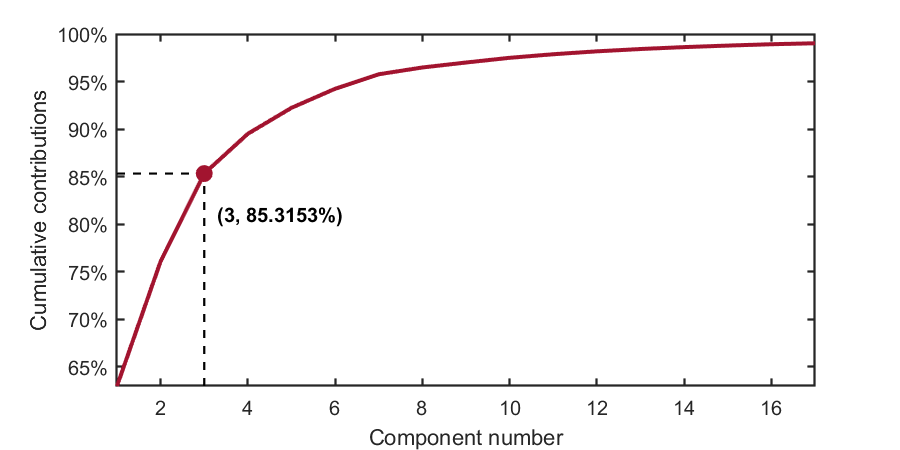


%　mapping data
mappingData = kpca1.score;

% Visualization
kplot = KernelPCAVisualization();
kplot.cumContribution(kpca1)

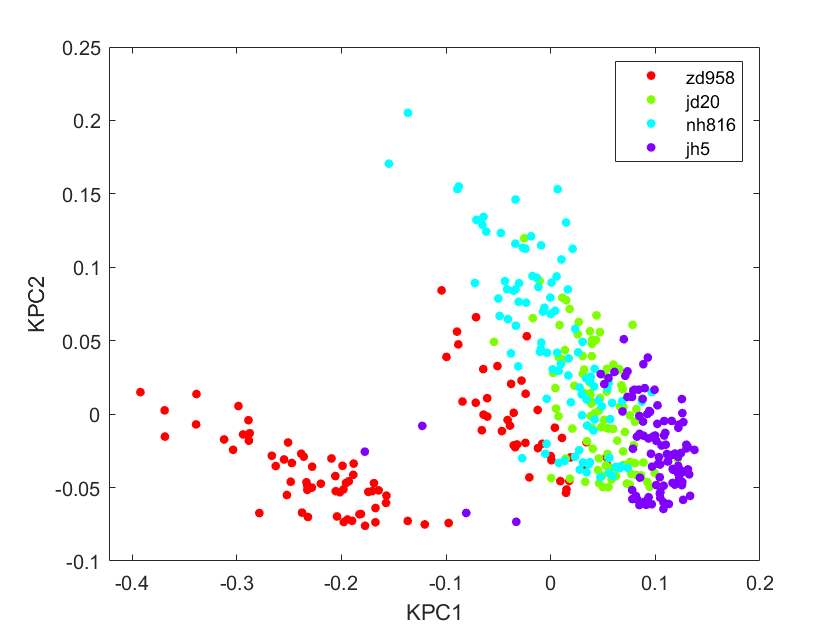

KPC1 = mappingData(:, 1);
KPC2 = mappingData(:, 2);
KPC3 = mappingData(:, 3);

figure;
gscatter(KPC1, KPC2, group)

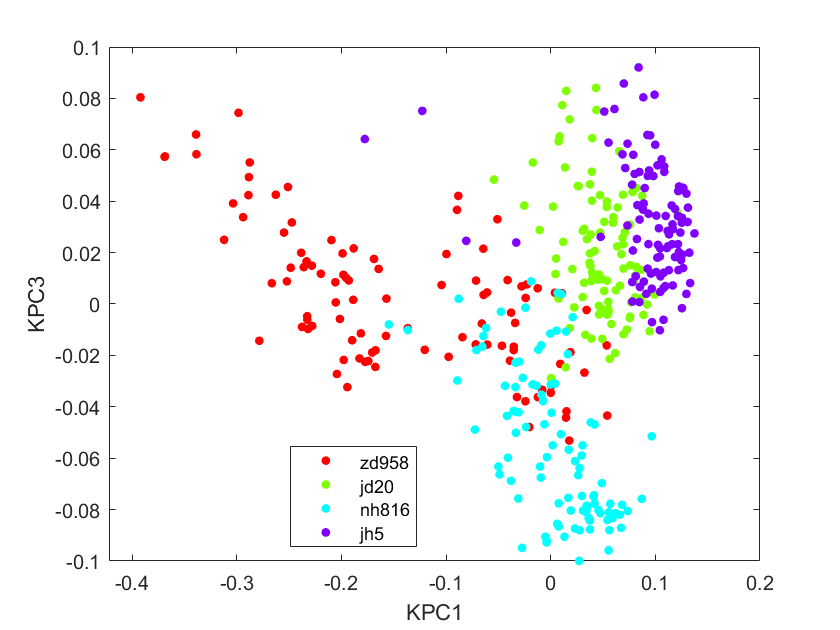

figure;
gscatter(KPC1, KPC3, group)

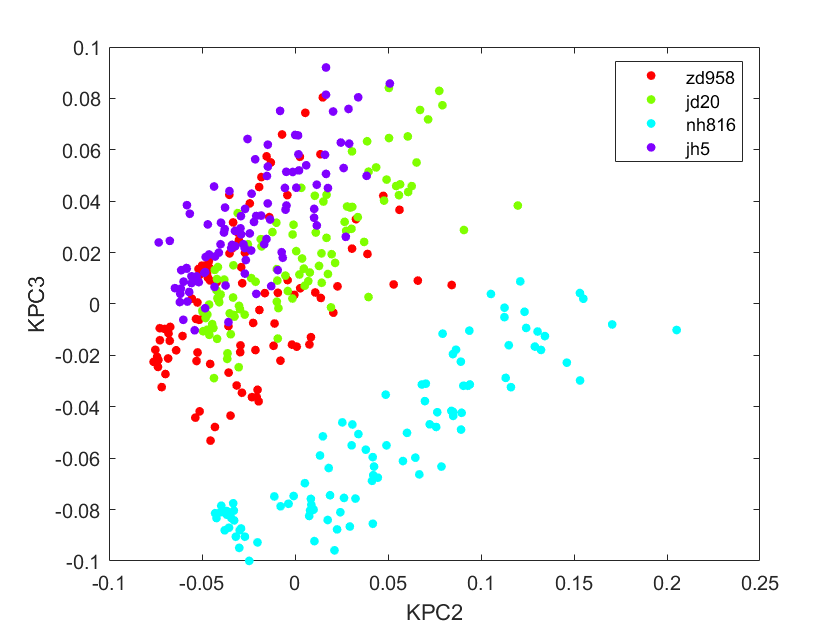

figure;
gscatter(KPC2, KPC3, group)

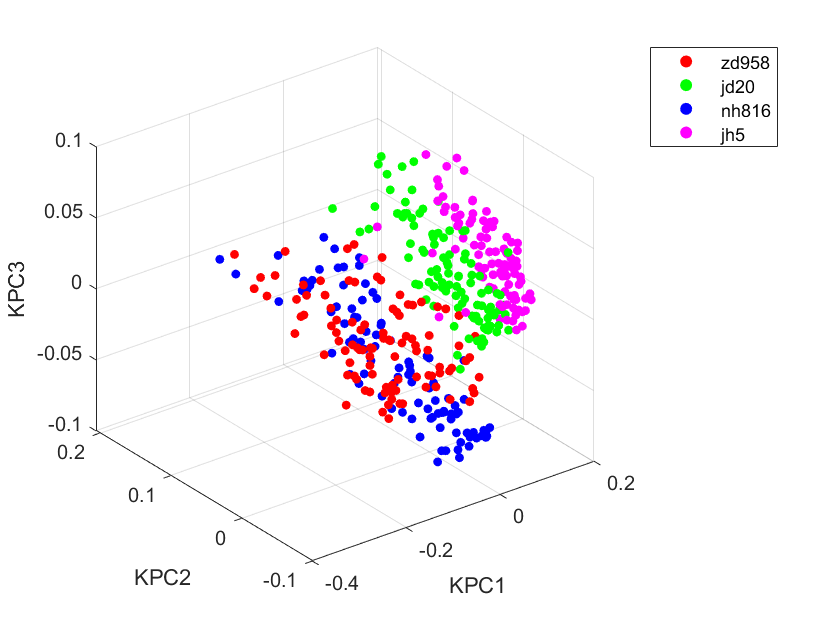

figure;
scatter3(KPC1(1:100), KPC2(1:100), KPC3(1:100), 20, "red", "filled")
hold on
scatter3(KPC1(101:200), KPC2(101:200), KPC3(101:200), 20, "green", "filled")
hold on
scatter3(KPC1(201:300), KPC2(201:300), KPC3(201:300), 20, "blue", "filled")
hold on
scatter3(KPC1(301:400), KPC2(301:400), KPC3(301:400), 20, "magenta", "filled")
xlabel('KPC1')
ylabel('KPC2')
zlabel('KPC3')
legend([{"zd958"},{"jd20"},{"nh816"}, {"jh5"}])

figure;

subplot(2,1,1)
plot(effshift, PC_coeff(:, 1));
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Loadings on PC1')
title('a')

x = ginput;
k = size(x,1);
hold on
for i = 1:k
    plot(x(i,1),x(i,2),'r+')    
    text(x(i,1), x(i,2), sprintf('%d',round(x(i,1))))
end 

subplot(2,1,2)
plot(effshift, PC_coeff(:, 3));
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Loadings on PC3')
title('b')

x = ginput;
k = size(x,1);
hold on
for i = 1:k
    plot(x(i,1),x(i,2),'r+')    
    text(x(i,1), x(i,2), sprintf('%d',round(x(i,1))))
end  
